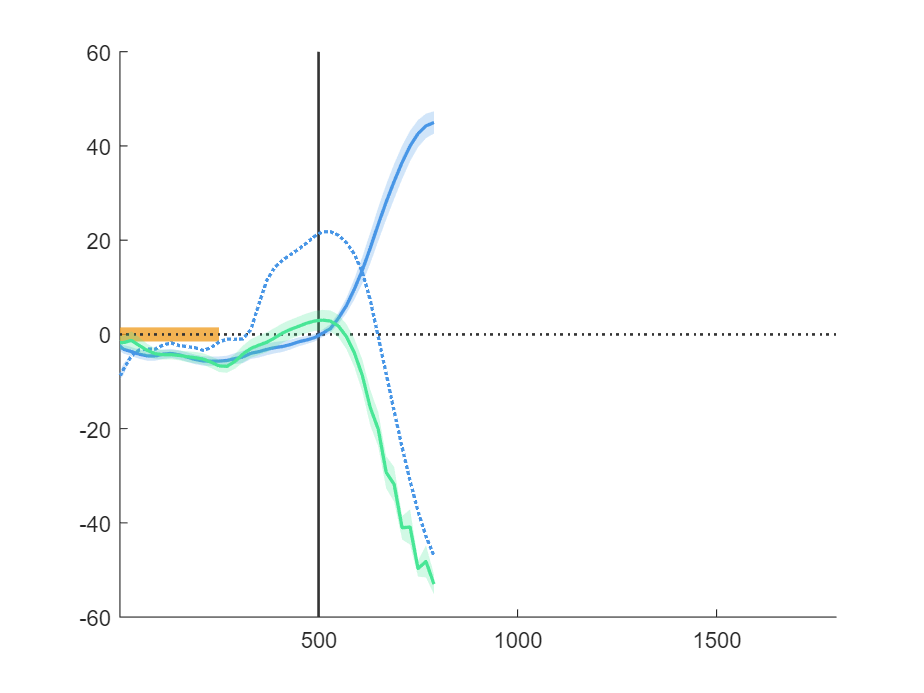

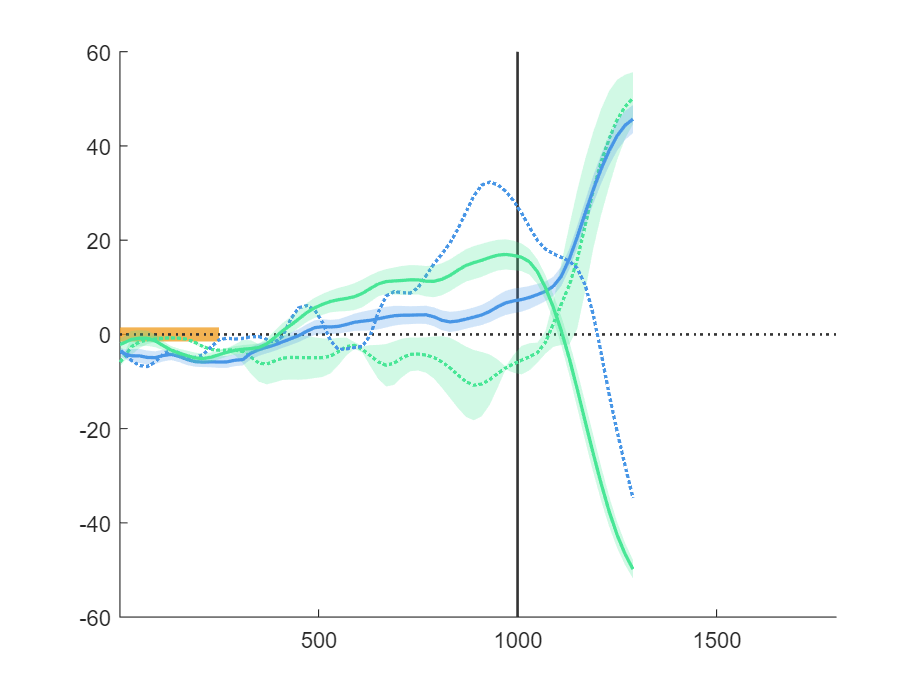

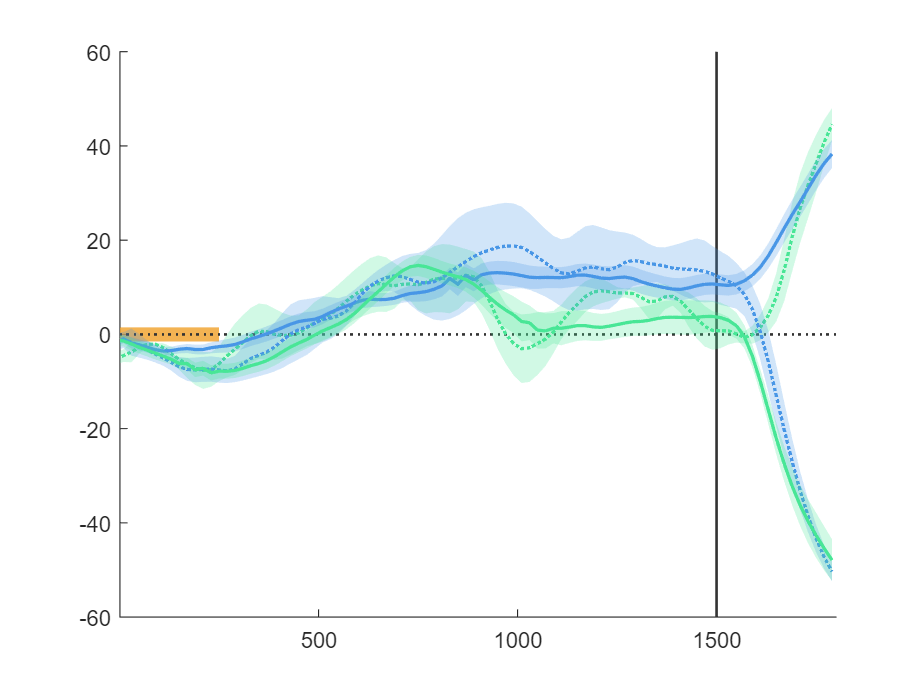

FPs = [.5 1 1.5];

MM = cell(3, 2, 2);

for f = 1:3
fp = FPs(f);

time_bin_edges = floor(obj.TimePointsIn(1)):20:1000*fp+300;
time_bin_center = time_bin_edges(1:end-1)+10;

Perf = ["Wrong", "Correct"];
figure(); hold on;

patch('XData', [0 250 250 0], 'YData', [-1.5 -1.5 1.5 1.5], 'FaceColor', GPSColor.Cue, 'FaceAlpha', 0.8, 'EdgeColor', 'none');

plot([-500 2000], [0 0], ':', 'LineWidth', 1.2, 'Color', [.2 .2 .2 .8]);
plot(1000*[fp fp], [-60 60], '-', 'LineWidth', 1.2, 'Color', [.2 .2 .2 .8]);

for j = 1:2
    for k = 1:2
        IndValid = find(ismember(obj.Performance, Perf(k)) & obj.FP==fp & obj.Ind.("Choose"+obj.Ports(j)));
    
        M = cell(1, length(time_bin_edges)-1);
        for i = 1:length(time_bin_edges)-1
            x = cellfun(@(x, y) x(y>=time_bin_edges(i) & y<time_bin_edges(i+1)), obj.AngleHead(IndValid), obj.TimeFromIn(IndValid), 'UniformOutput', false);
            z = cellfun(@(x, y) repmat(x, length(y), 1), num2cell(obj.Trial(IndValid)), x, 'UniformOutput', false);
            t = cellfun(@(y)    repmat(time_bin_center(i), length(y), 1), x, 'UniformOutput', false);
    
            pgo = cellfun(@(x, y) repmat(x, length(y), 1), obj.PortChosen(IndValid), x, 'UniformOutput', false);
            pco = cellfun(@(x, y) repmat(x, length(y), 1), obj.PortCorrect(IndValid), x, 'UniformOutput', false);
    
            x = cell2mat(x');
            z = cell2mat(z');
            t = cell2mat(t');
            pgo = cell2mat(pgo');
            pgo = string(pgo);
            pco = cell2mat(pco');
            pco = string(pco);
    
            M{i} = table(x, z, t, pgo, pco);
        end
    MM{f, j, k} = M;
    
    AngleHeadMean = cellfun(@(x) mean(x.x, 'omitnan'), M);
    AngleHeadSEM  = cellfun(@(x) std(x.x, 'omitnan'), M) ./ sqrt(cellfun(@(x) length(x.x), M));
    
    switch Perf(k)
        case {'Correct'}
            this_color = GPSColor().("Port"+obj.Ports(j));
            ls_this = "-";
        case {'Wrong'}
            this_color = GPSColor().("Port"+obj.Ports(3-j));
            ls_this = ":";
    end
    patch('XData', [time_bin_center flip(time_bin_center)], 'YData', [AngleHeadMean-AngleHeadSEM flip(AngleHeadMean+AngleHeadSEM)], ...
        'FaceColor', this_color, 'FaceAlpha', 0.25, 'EdgeColor', 'none')

    plot(time_bin_center, AngleHeadMean, 'Color', this_color, 'LineStyle', ls_this, 'LineWidth', 1.5);

    end
end
xlim([1 1500+300])
xticks(0:500:2000);
end


% p = strings(1, length(z));
% for i = 1:length(z)
%     p(i) = obj.ChosenPort(obj.Trial==z(i));
% end

auc = [];
for i = 1:length(MM{2, 1, 2}) 
    a = rocmetrics([MM{2, 1, 1}{i}.pco; MM{2, 1, 2}{i}.pco], [MM{2, 1, 1}{i}.x; MM{2, 1, 2}{i}.x], "L");
    auc = [auc a.AUC];
end

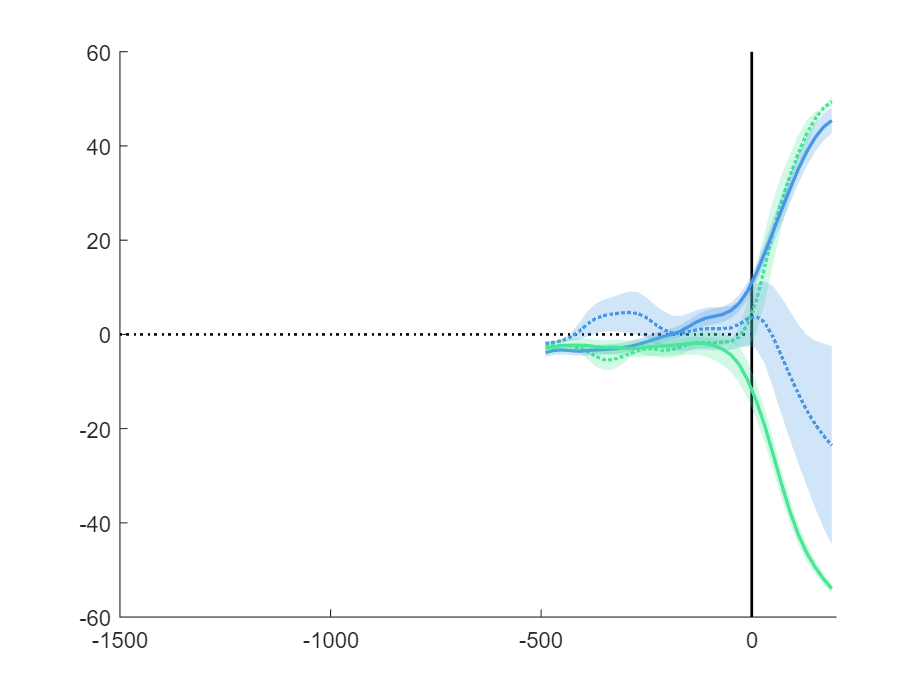

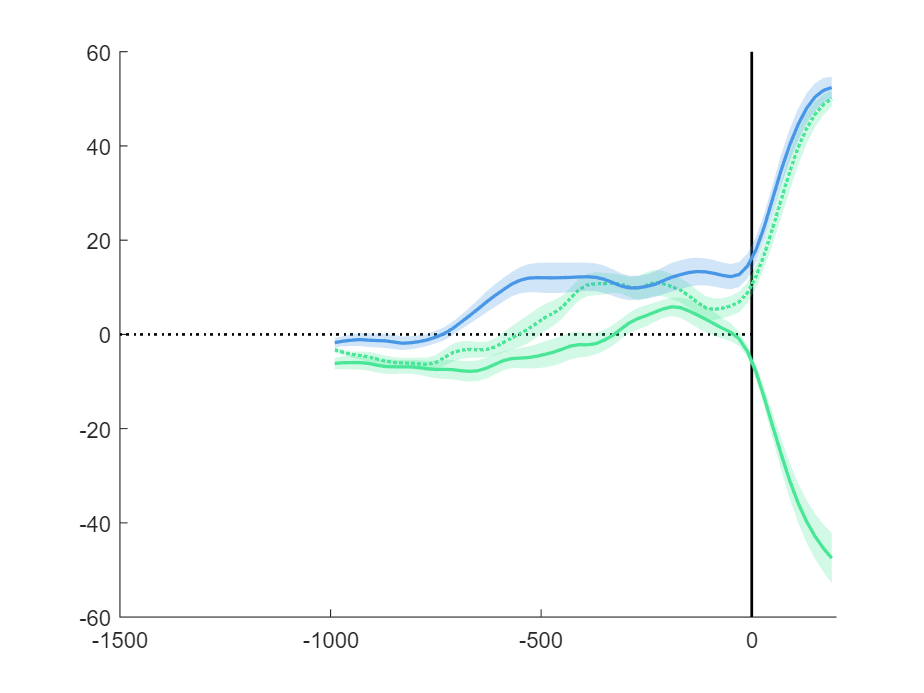

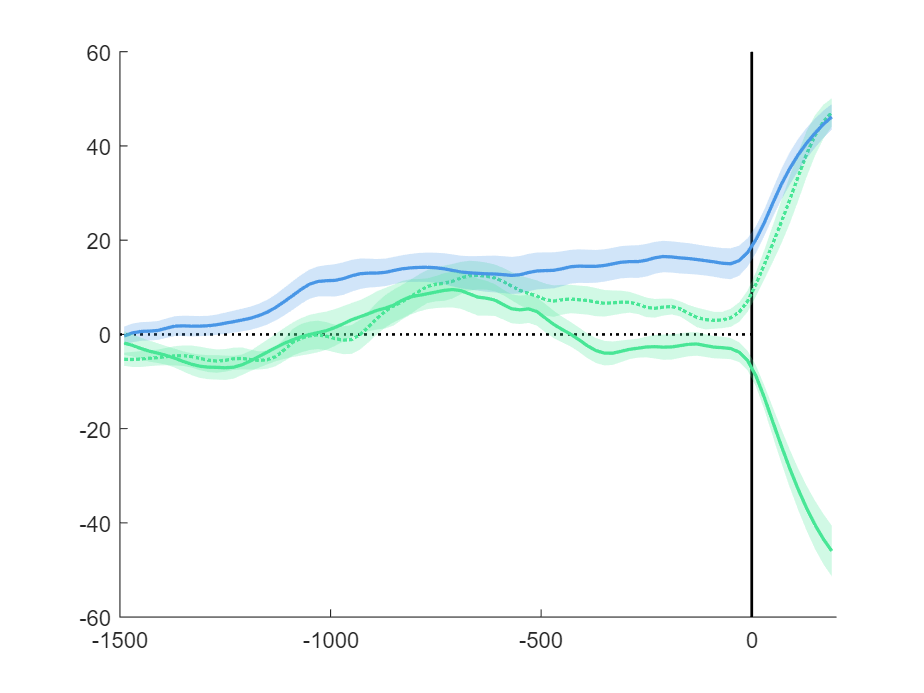

FPs = [.5 1 1.5];

for f = 1:3
fp = FPs(f);

time_bin_edges = -fp*1000:20:200;
time_bin_center = time_bin_edges(1:end-1)+10;

Perf = ["Wrong", "Correct"];
figure(); hold on;

plot([-1500 0], [0 0], ':k', 'LineWidth', 1.2);
plot([0 0], [-60 60], '--k', 'LineWidth', 1.2);
plot([0 0], [-60 60], '-k', 'LineWidth', 1.2);

for j = 1:2
    for k = 1:2
        IndValid = find(ismember(obj.Performance, Perf(k)) & obj.FP==fp & obj.Ind.("Choose"+obj.Ports(j)));
    
        M = cell(1, length(time_bin_edges)-1);
        for i = 1:length(time_bin_edges)-1
            x = cellfun(@(x, y) x(y>=time_bin_edges(i) & y<time_bin_edges(i+1)), obj.AngleHead(IndValid), obj.TimeFromOut(IndValid), 'UniformOutput', false);
            z = cellfun(@(x, y) repmat(x, length(y), 1), num2cell(obj.Trial(IndValid)), x, 'UniformOutput', false);
            t = cellfun(@(y)    repmat(time_bin_center(i), length(y), 1), x, 'UniformOutput', false);

            pgo = cellfun(@(x, y) repmat(x, length(y), 1), obj.PortChosen(IndValid), x, 'UniformOutput', false);
            pco = cellfun(@(x, y) repmat(x, length(y), 1), obj.PortCorrect(IndValid), x, 'UniformOutput', false);
    
            x = cell2mat(x');
            z = cell2mat(z');
            t = cell2mat(t');
            pgo = cell2mat(pgo');
            pgo = string(pgo);
            pco = cell2mat(pco');
            pco = string(pco);
    
            M{i} = table(x, z, t, pgo, pco);
        end
    
    AngleHeadMean = cellfun(@(x) mean(x.x, 'omitnan'), M);
    AngleHeadSEM  = cellfun(@(x) std(x.x, 'omitnan'), M) ./ sqrt(cellfun(@(x) length(x.x), M));
    
    switch Perf(k)
        case {'Correct'}
            this_color = GPSColor().("Port"+obj.Ports(j));
            ls_this = "-";
        case {'Wrong'}
            this_color = GPSColor().("Port"+obj.Ports(3-j));
            ls_this = ":";
    end
    patch('XData', [time_bin_center flip(time_bin_center)], 'YData', [AngleHeadMean-AngleHeadSEM flip(AngleHeadMean+AngleHeadSEM)], ...
        'FaceColor', this_color, 'FaceAlpha', 0.25, 'EdgeColor', 'none')

    plot(time_bin_center, AngleHeadMean, 'Color', this_color, 'LineStyle', ls_this, 'LineWidth', 1.5);

    end
end
xlim([-1500 200])
xticks(-1500:500:0);
end

A = MM{3,1,1}{1};
for i = 2:length(MM{3,1,1})
    A = [A; MM{3,1,1}{i}];
end
for i = 1:length(MM{3,2,2})
    A = [A; MM{3,2,2}{i}];
end


% 
% train_id = randperm(length(z), round(0.8*length(z)));
% test_id  = setdiff(1:length(z), train_id);
% 
% MdlLinear = fitcdiscr(x(train_id(randperm(length(train_id)))), pgo(train_id));
% 
% test = predict(MdlLinear, x(test_id));
% sum(test==pgo(test_id)) / length(test_id)